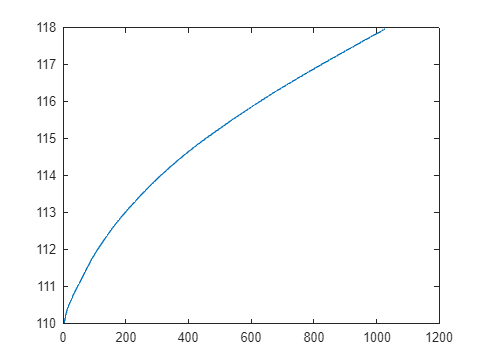

dataPath = "C:\Users\bluep\Documents\MATLAB\hwML\dataset-3b.xlsx";
dataTable_details = readtable(dataPath, 'Sheet', 'QH_S1');
dataH1 = dataTable_details(:,"H_S1");
dataQ1 = dataTable_details(:,"Q_S1");

flattenedDataH1 = table2array(dataH1);
flattenedDataQ1 = table2array(dataQ1);

% Plot the data
plot(flattenedDataQ1, flattenedDataH1);


% Reshape the data to column vectors
x = flattenedDataQ1(:);
y = flattenedDataH1(:);

% Remove duplicate entries
unique_indices = unique([x, y], 'rows');
unique_x = unique_indices(:, 1);
unique_y = unique_indices(:, 2);

% Normalize the data (optional but might help in some cases)
normalized_x = (unique_x - mean(unique_x)) / std(unique_x);
normalized_y = (unique_y - mean(unique_y)) / std(unique_y);

% Fit a polynomial model
polyModel = fittype('poly5');
fitResult = fit(normalized_x, normalized_y, polyModel, 'Exclude', []);

% Obtain the fitted values
fittedValues = feval(fitResult, normalized_x);

% Create new x-values for the fitted curve
new_x = linspace(min(normalized_x), max(normalized_x), 100); % Adjust the number of points as needed

% Evaluate the fitted curve at the new x-values
fittedCurve = feval(fitResult, new_x);

% Calculate R-squared for the fit
SSres = sum((normalized_y - fittedValues).^2);
SStotal = (length(normalized_y) - 1) * var(normalized_y);
R_squared = 1 - SSres / SStotal;

% Calculate Mean Squared Error (MSE)
MSE = sum((normalized_y - fittedValues).^2) / length(normalized_y);

% Display the results
fprintf('R-squared: %.4f\n', R_squared);

R-squared: 0.9998


fprintf('Mean Squared Error (MSE): %.4f\n', MSE);

Mean Squared Error (MSE): 0.0002


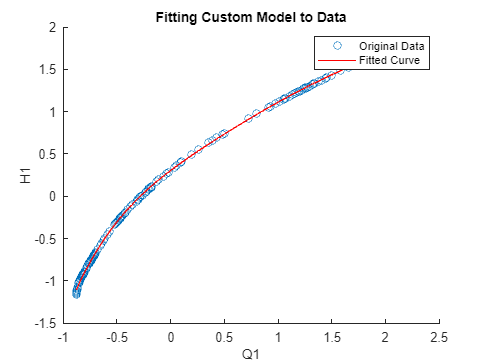


% Plot the original data and the fitted curve
figure;
scatter(normalized_x, normalized_y, 'o', 'DisplayName', 'Original Data');
hold on;
plot(new_x, fittedCurve, 'r-', 'DisplayName', 'Fitted Curve');
hold off;

legend('show');
xlabel('Q1');
ylabel('H1');
title('Fitting Custom Model to Data');